# Cviceni 9

## Rasterizace primky

### DDA algoritmus

- Z koncovych bodu [x1, y1] a [x2, y2] urci smernici m.

- Inicializuj bod [x, y] hodnotou [x1, y1].

- Dokud je x <= x2 opakuj:  

                    -  Vykresli bod [x, zaokrouhlene(y)] 

                    -  x = x + 1

                    - y = y + m

Tento algoritmus je jen pro 0 <= m <=1 pro  ostatní m je potřeba upravit. pro  | m | > 1 se usecka primyka k y a tak se y zvetsuje o 1 a x o 1/m

## UKOL 1

Naprogramujet funkci, ktera jako argument bude brat bod A (dvourozmerny vektor), bod B (take dvourozmerny  vektor) a velikost vysledneho obrazku (take dvourozmerny vektor). Vystupem bude obrazek o velikosti vysledneho obrazku a v nem vykreslena usecka AB.

Primka A = [x1,y1], B = [x2,y2]

Smernice m = (y2 - y1) / (x2-x1)

### Bresenhamuv algoritmus

bresenhamuv_algoritmus.m  -- pro nazornost jen pro primky prichylujici se k ose x.

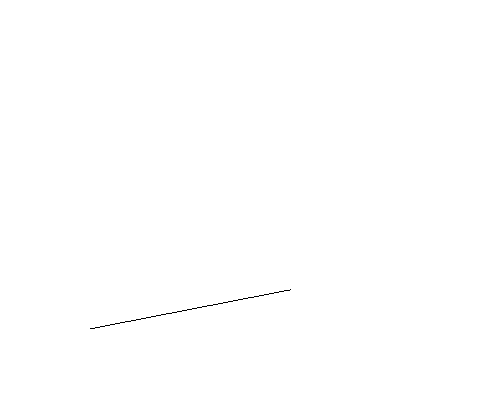

 usecka = bresenhamuv_algoritmus([-100,1], [100,40],[300,300]);
 
 figure, imshow(usecka);

### Bresenhamuv algoritmus - prerusovana cara

ba_prerusovana.m  -- pro nazornost jen pro primky prichylujici se k ose x 

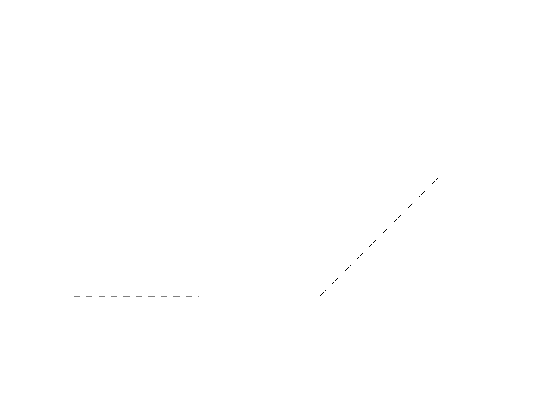

 usecka = ba_prerusovana([-100,1], [100,1],[300,300], 10);  % posledni argument = delka useku
 usecka2 = ba_prerusovana([-100,-100], [100,99],[300,300], 10);  % posledni argument = delka useku
 
 figure,
 subplot(1,2,1), imshow(usecka);
 subplot(1,2,2), imshow(usecka2);

### Bresenhamuv algoritmus - prerusovana cara stejna delka useku

ba_prerusovana2.m  -- pro nazornost jen pro primky prichylujici se k ose x 

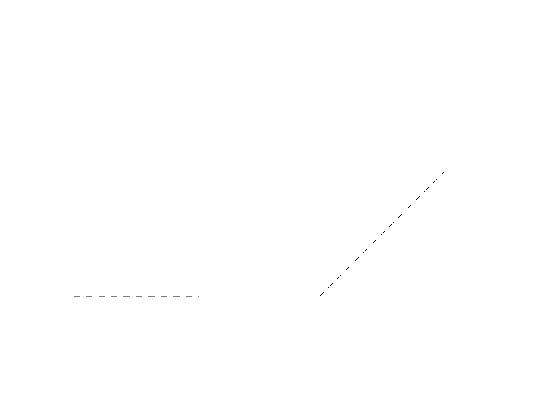

usecka = ba_prerusovana2([-100,1], [100,1],[300,300], 10);  % posledni argument = delka useku
usecka2 = ba_prerusovana2([-100,-100], [100,99],[300,300], 10);  % posledni argument = delka useku

figure,
subplot(1,2,1), imshow(usecka);
subplot(1,2,2), imshow(usecka2);

### Bresenhamuv algoritmus - silna cara

ba_silna.m -- pro nazornost jen pro primky prichylujici se k ose x 

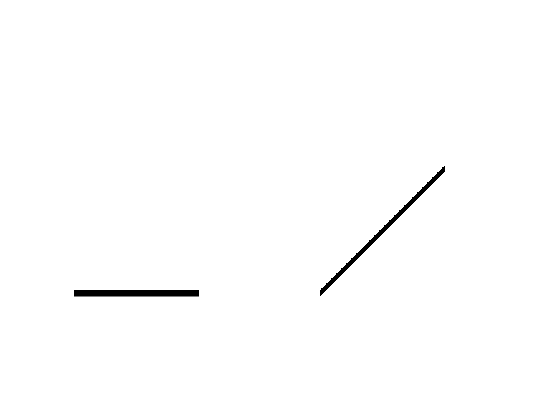

usecka = ba_silna([-100,1], [100,1],[300,300], 10);  % posledni argument = tlousktka
usecka2 = ba_silna([-100,-100], [100,99],[300,300], 10);  % posledni argument = tlousktka

figure,
subplot(1,2,1), imshow(usecka);
subplot(1,2,2), imshow(usecka2);

### Bresenhamuv algoritmus - silna cara - stejna tloustka

ba_silna2.m -- pro nazornost jen pro primky prichylujici se k ose x 

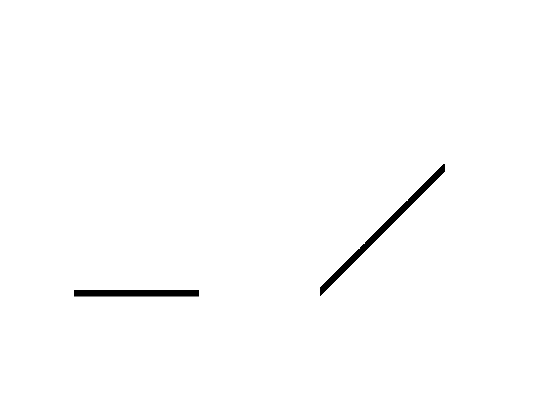

usecka = ba_silna2([-100,1], [100,1],[300,300], 10);  % posledni argument = tlousktka
usecka2 = ba_silna2([-100,-100], [100,99],[300,300], 10);  % posledni argument = tlousktka

figure,
subplot(1,2,1), imshow(usecka);
subplot(1,2,2), imshow(usecka2);

## UKOL 2

Podivejte se na funkce 

- bresenhamuv_algoritmus.m

- ba_prerusovana.m

- ba_prerusovana2.m  

- ba_silna.m

- ba_silna2.m

Zamerte se na to, jak se jednotlive kody lisi.

## UKOL 3

Upravte funkci z prvniho ukolu, tak aby vykreslovala prerusovanou caru a silnou caru. Stjene, jako ba_silna2 a ba_prerusovana2.

## Rasterizace kruznice

ba_kruznice.m -- podivejte se na kod

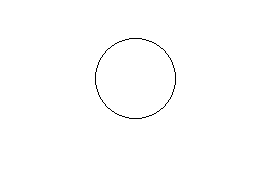

kruznice = ba_kruznice(40, [50,50], [100,100]);
figure, imshow(kruznice);

## Detekce car

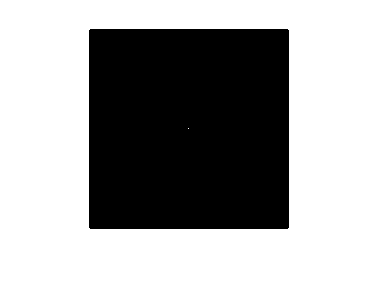

% Obrazek obsahujici nekolik bilych bodu

f = zeros(200,200);
f(1,1) = 1; 
f(1,end) = 1;
f(end,1) =1;
f(end,end)= 1;
f(100,100)=1;
figure, imshow(f);

## Houghova transformace

Obraz f obsahuje 5 bilych bodu, H obsahuje 5 sinusovek (i vodorovná linie je jedna z nich). Jejich pruseciky predstavuji pocet bodu na jedne primce. X osa predstavuje parametr theta, Y r.

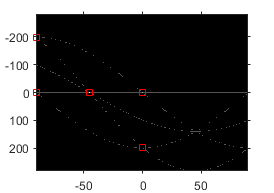

[H, theta, r] = hough(f);
imshow(H,[], 'XData', theta, 'YData', r ,'InitialMagnification', 'fit');
axis on, axis normal   
peaks = houghpeaks(H,5);
hold on;
plot(theta(peaks(:,2)), r(peaks(:,1)), 'linestyle', 'none', 'marker', 's', 'color','r'); 

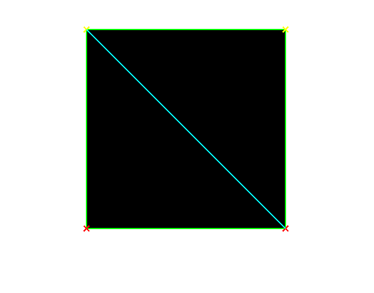

lines = houghlines(f,theta,r,peaks,'FillGap',200);
figure, imshow(f), hold on
max_len = 0;
for k = 1:length(lines)
 xy = [lines(k).point1; lines(k).point2];
 plot(xy(:,1),xy(:,2),'LineWidth',1,'Color','green');

 % plot beginnings and ends of lines
 plot(xy(1,1),xy(1,2),'x','LineWidth',1,'Color','yellow');
 plot(xy(2,1),xy(2,2),'x','LineWidth',1,'Color','red');

 % determine the endpoints of the longest line segment 
 len = norm(lines(k).point1 - lines(k).point2);
 if ( len > max_len)
   max_len = len;
   xy_long = xy;
 end
end

% highlight the longest line segment
plot(xy_long(:,1),xy_long(:,2),'LineWidth',1,'Color','cyan');

## UKOL 4

Naprogramujte funkci  najdi_primku, ktera bere jako vstup cernobily obrazek a vraci rovnici primky, ktera je v obrazku a pocet bodu na primce.

 Rovnice přímky:  r = x*cos(f) + y*sin(f) 

ALGORITMUS

- Vynulujeme akumulator A[ri,fj] pro vsechna i = 1,…, M a j = 1,…, N (M,N urcuji pocet vzorku. Cim je cislo vetsi, tim je rovnice presnejsi, ale algoritmus pomalejsi)

- Projdeme cely obraz a pro kazdy cerny bod v obraze (xk,yk) a pro vsechna fj spocitame    rj = xk*cos(fj) +  y * sin(fj) a inkrementujeme A[rj, fj] (najdeme mezi vsemi r nejblizsi hodnotu k vypocitanemu r)

- Po pruchodu celym obrazem hodnota v akumulatoru A[r,f] urcuje pocet bodu na primce    r = x*cos(f) + y*sin(f).                Najdeme maximum a tuto primku vratime.

 V matlabu: 

str = ['rovnice: ', num2str(r(v)), ' = x*cos ', num2str(fi(w)), ' + y*sin ', num2str(fi(w))];
display(str);

 f má hodnotu od -90 do 90

 r má hodnotu od –D do D, kde D je velikost diagonály v obraze